# **Problem Set 1 / Problem 2 - ***Mean and Variance of Random Variables*

**Given **$Y$** and **$X$** random variables (RV).**

$X$ has mean and variance of $\mu_X$ and $\sigma_X^2$ , respectively.

$Y$ is defined as:


$$Y=\frac{X-E\left(X\right)}{\sqrt{\textrm{Var}\left(X\right)}}=\frac{X-\mu_X }{\sqrt{\sigma_X^2 }}$$


% set seed to ensure reproducability
rng(1)

## Task 1

**Analytically compute **$E\left(Y\right)$**.**

**Utilizing:**


$$a+b*E\left(V\right)=E\left(a+b*V\right)$$



$$E\left(Y\right)=E\left(\frac{X-E\left(X\right)}{\sqrt{\textrm{Var}\left(X\right)}}\right)$$



$$E\left(Y\right)=\frac{1}{\sqrt{\textrm{Var}\left(X\right)}}*E\left(X-E\left(X\right)\right)=\frac{1}{\sqrt{\textrm{Var}\left(X\right)}}*\left(E\left(X\right)-E\left(X\right)\right)=\frac{1}{\sqrt{\textrm{Var}\left(X\right)}}*0=0$$


## Task 2

**Analytically compute **$\textrm{Var}\left(Y\right)$**.**

**Utilizing:**


$$b^2 *\textrm{Var}\left(V\right)=\textrm{Var}\left(a+b*V\right)$$



$$\mathrm{Var}\left(Y\right)=\mathrm{Var}\left(\frac{X-E\left(X\right)}{\sqrt{\mathrm{Var}\left(X\right)}}\right)$$



$$\textrm{Var}\left(Y\right)={\left(\frac{1}{\sqrt{\textrm{Var}\left(X\right)}}\right)}^2 *\textrm{Var}\left(X\right)=\frac{1}{\textrm{Var}\left(X\right)}*\textrm{Var}\left(X\right)=\frac{\textrm{Var}\left(X\right)}{\textrm{Var}\left(X\right)}=1$$


## Task 3

**Interpret the resulting random variable **$Y$**.**

$Y$ is expressed by the RV of $X$, for which the participating statistics, that is the *Expected Value (mean)* and the *Variance* can be choosen arbitrarily.

Regardless of the values of $X$, $Y$ has an *expected value* of 0 and a *variance* of 1. Therefore, $Y$ can be seen as a function which takes an arbitrary RV $X$ as input, and transforms it into a RV with *mean* of 0 and *variance* of 1.

This is essentially the **standardization** function, which, considering a *normal (Gaussian) distribution* for the RV's, shifts the position of the distribution to be centered around zero and squeezes or stretches it to have a *standard deviation* (and *variance*) of 1, utilizing the arbitrarily choosen statistics, $E\left(X\right)$ and $\textrm{Var}\left(X\right)$.

## Task 4

**Reformulate the equation and show how an RV with arbitrary mean and variance can be obtained based on a standard Gaussian RV. Verify your insight in Matlab.**

Since the *standard Gaussian RV* is $Y$, we need to express $X$ by $Y$ from the equation.


$$X=E\left(X\right)+\textrm{Var}\left(X\right)*Y$$


As for an example RV $X_1$ with *expected value* of 8 and *variance* of 3.5,


$$X_1 =E\left(X_1 \right)+\mathrm{Var}\left(X_1 \right)*Y=8+3\ldotp 5*Y$$


And as for RV $X_2$, -10 and 0.8, respectively,


$$X_2 =E\left(X_2 \right)+\mathrm{Var}\left(X_2 \right)*Y=-10+0\ldotp 8*Y$$


Verification through visualizations:

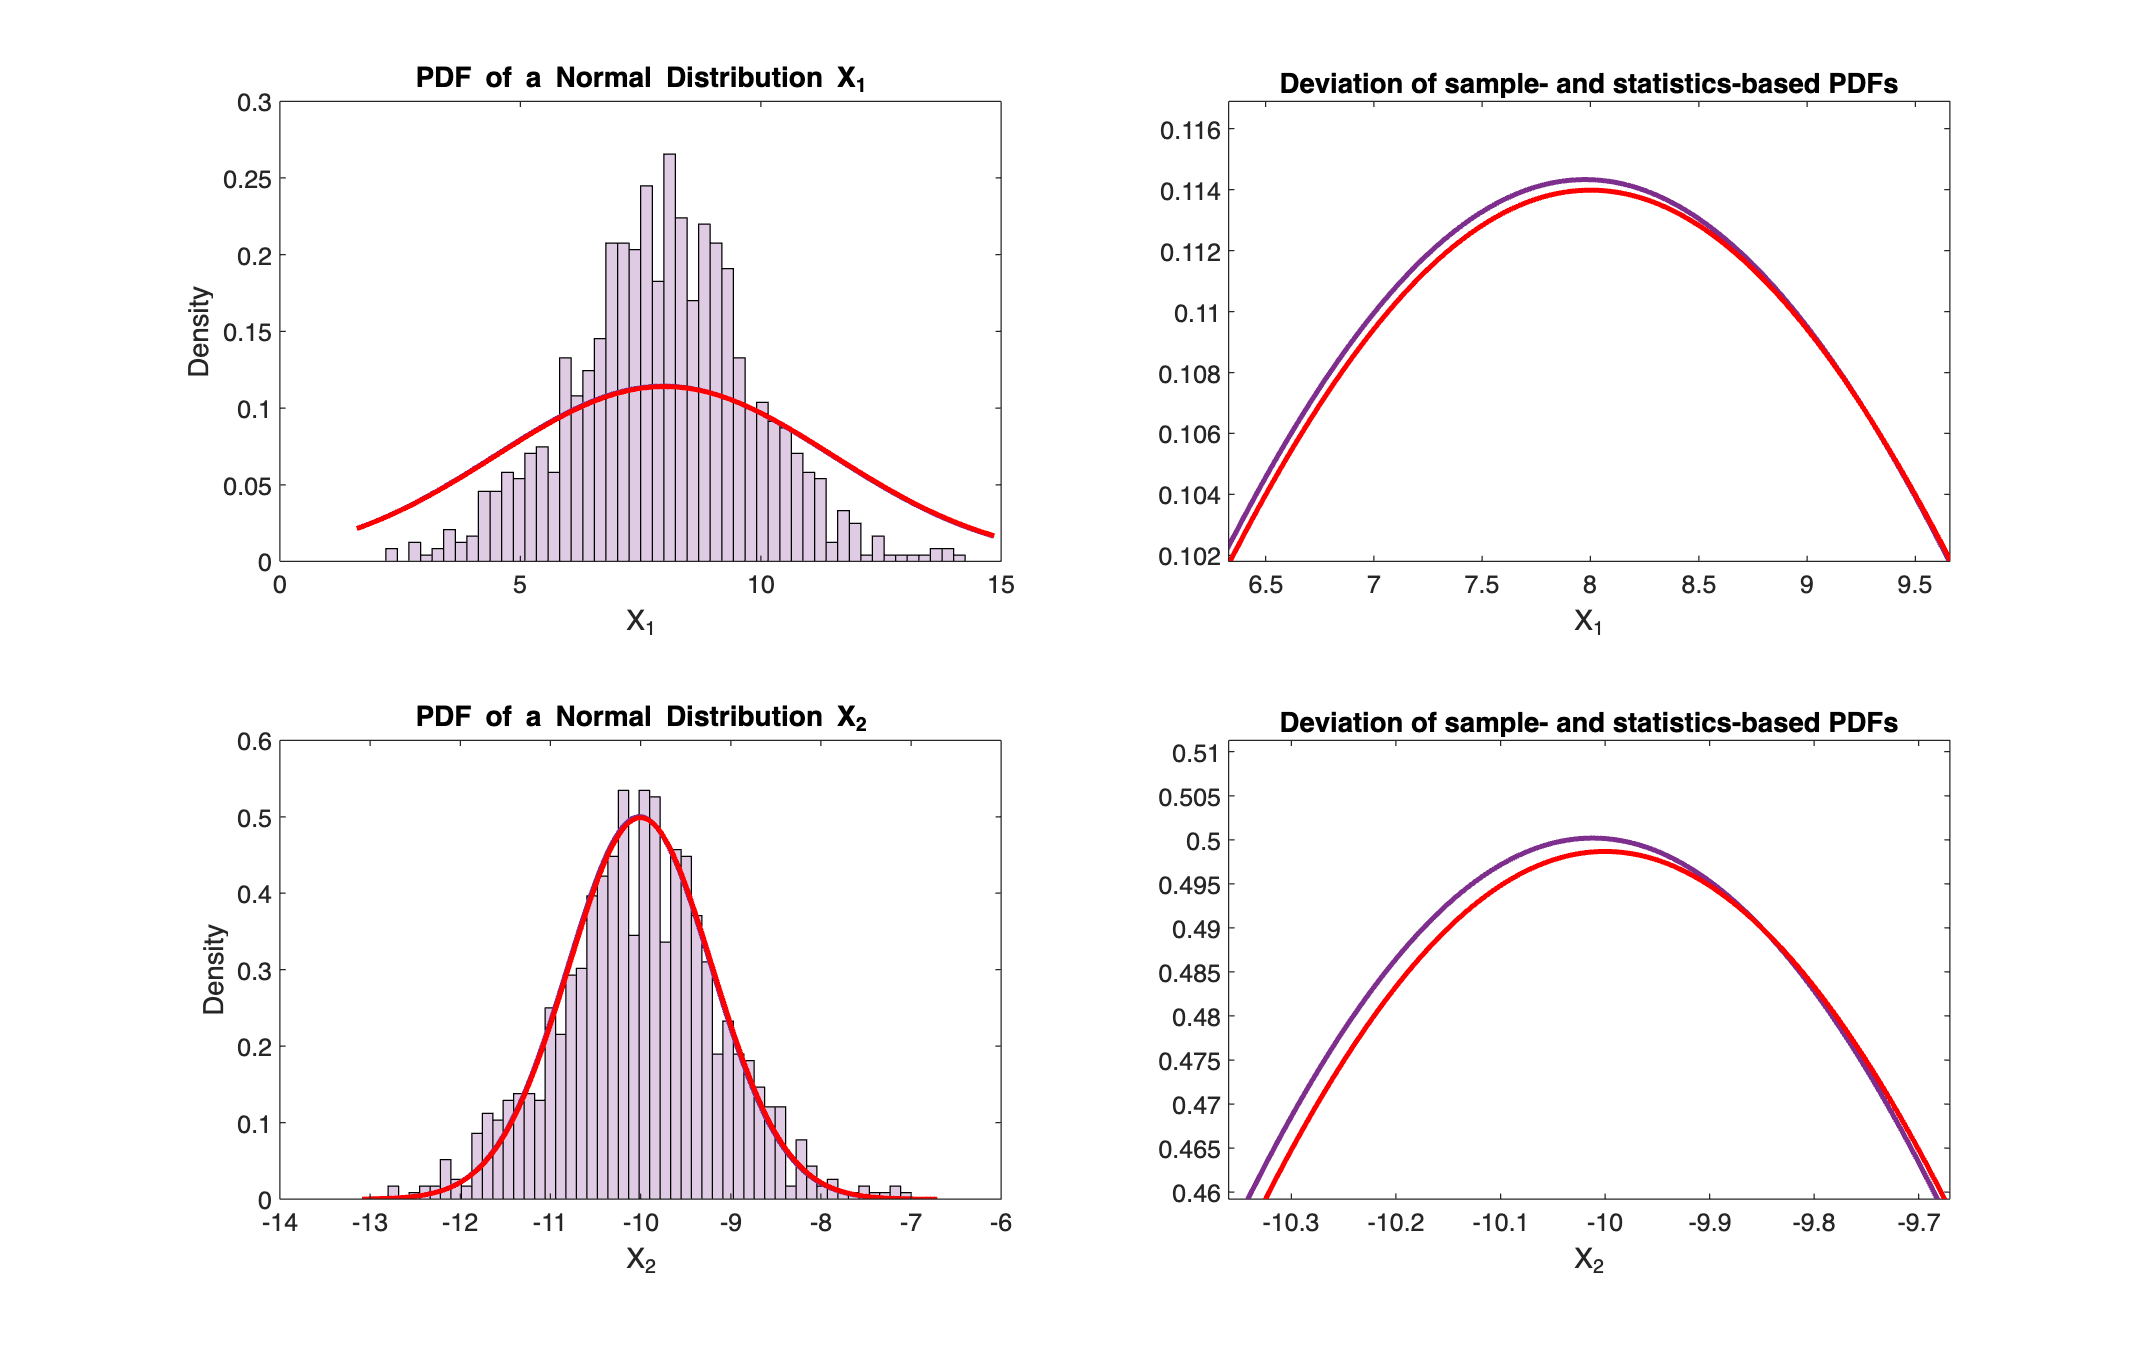

% arbitrary X, X_1

% statistics
inp_X_mu = 8;
inp_X_var = 3.5;

% Z, a 'big enough' sample from Y
%     data points approximating the standard normal distribution
Z = randn(1000, 1);

% equation of X_1
X_1 = inp_X_mu + sqrt(inp_X_var) * Z;

% plot

figure('units','normalized','outerposition',[0 0 1 1]);
grid on;

% histogram
subplot(2, 2, 1);
histogram(X_1, 50, Normalization='pdf', FaceColor='#7E2F8E', FaceAlpha=0.25);
hold on;

%

ax = gca;
X_1_linspc = linspace(ax.XLim(1), ax.XLim(2), 1000);

% pdf (using the actual pdf statistics)

plot(X_1_linspc, normpdf(X_1_linspc, mean(X_1), var(X_1)), Color='#7E2F8E', LineWidth=2);
hold on;

% pdf (using input (desired) statistics)

plot(X_1_linspc, normpdf(X_1_linspc, inp_X_mu, inp_X_var), Color='red', LineWidth=2);

title('PDF of a Normal Distribution X_1');
xlabel('X_1');
ylabel('Density');
hold off;

% plot 'zoom'
subplot(2, 2, 2);
X_1_linspc = linspace(0, 20, 1000);

% pdf (using the actual pdf statistics)
plot(X_1_linspc, normpdf(X_1_linspc, mean(X_1), var(X_1)), Color='#7E2F8E', LineWidth=2);
hold on;

% pdf (using input (desired) statistics)
plot(X_1_linspc, normpdf(X_1_linspc, inp_X_mu, inp_X_var), Color='red', LineWidth=2);

xlim([6.33 9.66]);
ylim([0.1018 0.1169]);
xlabel('X_1');
title('Deviation of sample- and statistics-based PDFs');

hold off;
% arbitrary X, X_2

% new input statistics
inp_X_mu = -10;
inp_X_var = .8;

% new equation for X_2
X_2 = inp_X_mu + sqrt(inp_X_var) * Z;

% continue plotting

% histogram
subplot(2, 2, 3);
histogram(X_2, 50, Normalization='pdf', FaceColor='#7E2F8E', FaceAlpha=0.25);
hold on;

%
ax = gca;
X_2_linspc = linspace(ax.XLim(1), ax.XLim(2), 1000);

% pdf (using the actual pdf statistics)
plot(X_2_linspc, normpdf(X_2_linspc, mean(X_2), var(X_2)), Color='#7E2F8E', LineWidth=2);
hold on;

% pdf (using input (desired) statistics)
plot(X_2_linspc, normpdf(X_2_linspc, inp_X_mu, inp_X_var), Color='red', LineWidth=2);

title('PDF of a Normal Distribution X_2');
xlabel('X_2');
ylabel('Density');
hold off;

% plot 'zoom'
subplot(2, 2, 4);

% pdf (using the actual pdf statistics)
plot(X_2_linspc, normpdf(X_2_linspc, mean(X_2), var(X_2)), Color='#7E2F8E', LineWidth=2);
hold on;

% pdf (using input (desired) statistics)
plot(X_2_linspc, normpdf(X_2_linspc, inp_X_mu, inp_X_var), Color='red', LineWidth=2);

xlim([-10.36 -9.67]);
ylim([0.4592 0.5113]);
xlabel('X_2');
title('Deviation of sample- and statistics-based PDFs');

hold off;

We can see that using 1000 data points as the sample of $Y$ in both of the above samples, by scaling and shifting by the arbitrary statistics of $X$, we get a close approximation of the PDF associated with the given and desired statistics.

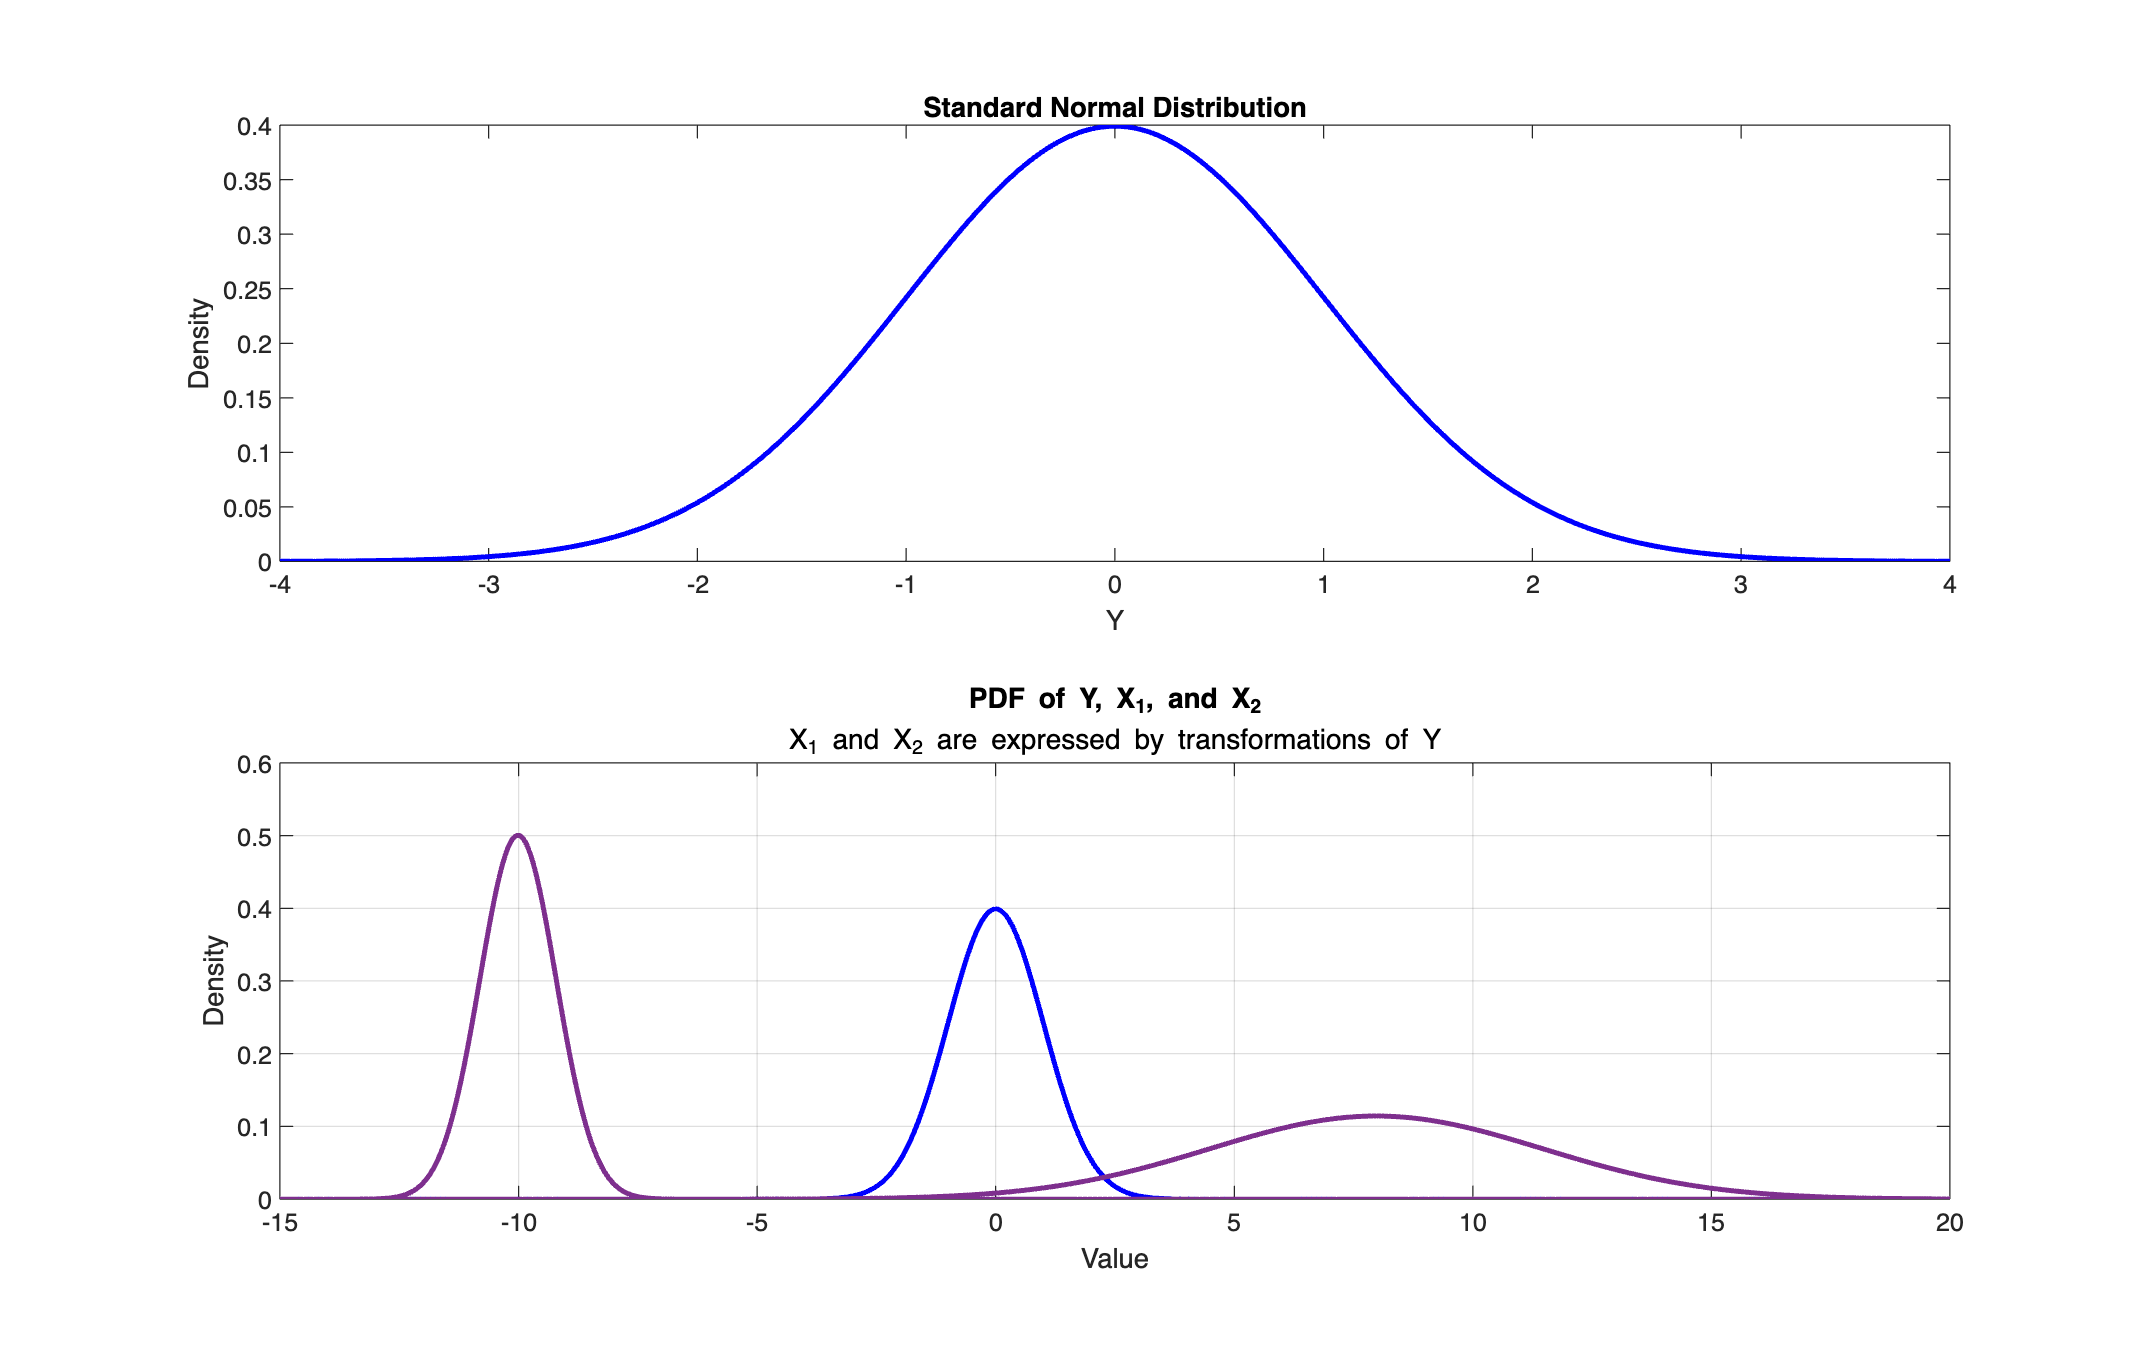

% Y, Standard Normal Distribution
%   Y ~ N(0, 1)
%       mean(Y) = 0
%       var(Y)  = 1

% construct PDF of Y
interval = -4:0.01:4;
Y = pdf('Normal', interval, 0, 1);

% plot

figure('units','normalized','outerposition',[0 0 1 1]);
grid on;

subplot(2, 1, 1);
plot(interval, Y, Color='b', LineWidth=2);
title('Standard Normal Distribution');
xlabel('Y');
ylabel('Density');

% plot Y, X_1, and X_2 on a single chart

interval = -15:0.01:20;
Y = pdf('Normal', interval, 0, 1);

% Y
subplot(2, 1, 2);
plot(interval, Y, Color='b', LineWidth=2);
grid on;
hold on;

% X_1
ax = gca;
X_1_linspc = linspace(ax.XLim(1), ax.XLim(2), 1000);
plot(X_1_linspc, normpdf(X_1_linspc, mean(X_1), var(X_1)), Color='#7E2F8E', LineWidth=2);
hold on;

% X_2
ax = gca;
X_2_linspc = linspace(ax.XLim(1), ax.XLim(2), 1000);
plot(X_2_linspc, normpdf(X_2_linspc, mean(X_2), var(X_2)), Color='#7E2F8E', LineWidth=2);

title('PDF of Y, X_1, and X_2');
subtitle('X_1 and X_2 are expressed by transformations of Y');
xlabel('Value');
ylabel('Density');
hold off;

#### Task 5

**Based on the previous task, find a method to generate a random vector with arbitrary mean vector and arbitrary (hermitian and positive definite) covariance matrix based on a standard multivariate Gaussian random vector.**

We are dealing with a similar situation as in **Task 4**, in the sense of transforming a normal distribution into a new one with arbitrary mean and variance. Yet here, instead of a single *RV* and its corresponding PDF plotted on a 2-dimensional plane, we go into additional dimensions, such as $D=n+1$, where $n\ge 2$ denotes the number of *RV*'s.

Considering $D=2$, we arrive at the following initial setup compared to *Task 4*:

As for the transformation:


$$C_{X_1 ,X_2 } =\left\lbrack \begin{array}{cc}
\mathrm{Var}\left(X_1 \right) & \mathbf{Cov}\left({\mathit{\mathbf{X}}}_1 ,{\mathit{\mathbf{X}}}_2 \right)\\
\mathbf{Cov}\left({\mathit{\mathbf{X}}}_1 ,{\mathit{\mathbf{X}}}_2 \right) & \mathrm{Var}\left(X_2 \right)
\end{array}\right\rbrack$$


With concrete values:

Given the *standard normal (Gaussian) distributions*, $Y_1$ and $Y_2$,


$$Y_1 ,Y_2 ~N\left(0,\;1\right)$$


Given the following arbitrary *mean vector* and *covariance matrix*,


$$M=\left\lbrack 3,2\right\rbrack$$



$$C=\left\lbrack \begin{array}{cc}
2 & 0\ldotp 5\\
0\ldotp 5 & 1
\end{array}\right\rbrack$$


The transformations to obtain $X_1 ,X_2$ is visualized as follows:

% bivariate standard normal distribution
mu_original = [0; 0];
cov_original = [1 0; 0 1];

% grid
[Y1, Y2] = meshgrid(linspace(-8, 8), linspace(-8, 8));

% original density
pdf_original = mvnpdf([Y1(:), Y2(:)], mu_original', cov_original);
pdf_original = reshape(pdf_original, size(Y1));

% plot

figure('units','normalized','outerposition',[0 0 1 1]);

% surface
subplot(2, 2, 1);
surf(Y1, Y2, pdf_original, 'EdgeColor', 'none');
colormap(jet);
colorbar;
xlabel('Y1'); ylabel('Y2'); zlabel('Density');
title('3D Surface');

% heatmap
subplot(2, 2, 2);
imagesc(linspace(-8, 8), linspace(-8, 8), pdf_original);
set(gca, 'YDir', 'normal');
colormap(jet);
colorbar;
xlabel('Y1'); ylabel('Y2');
title('2D Heatmap');


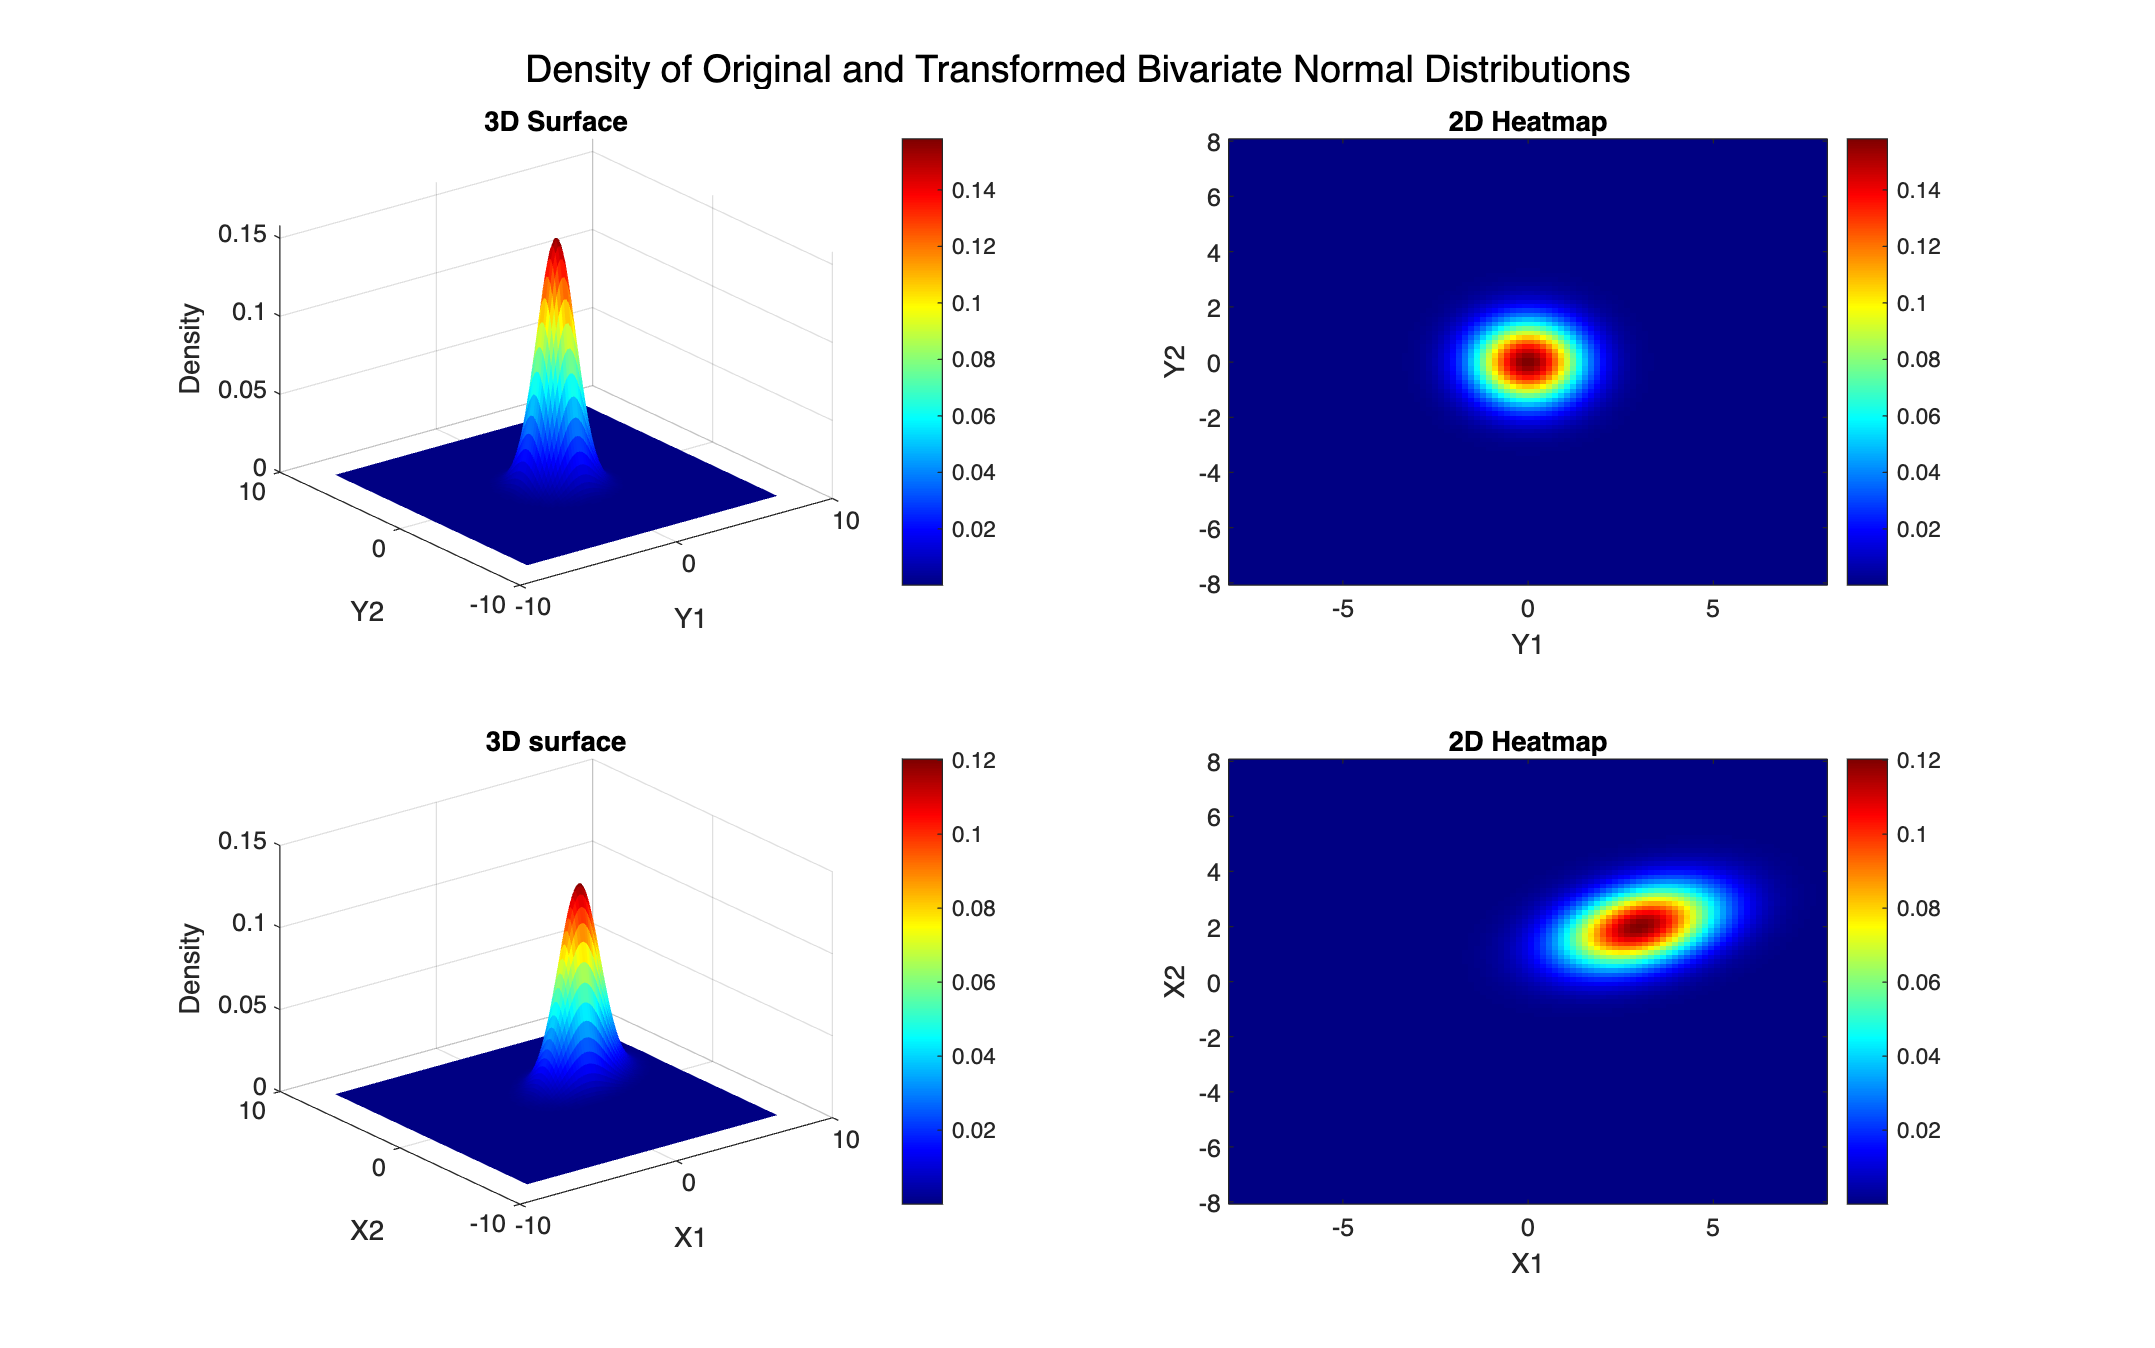

% arbitrary mean vector and covariance matrix for transformation
mu_transform = [3; 2];
cov_transform = [2 0.5; 0.5 1];

% grid
[X1, X2] = meshgrid(linspace(-8, 8), linspace(-8, 8));

% transformed density
pdf_transformed = mvnpdf([X1(:), X2(:)], mu_transform', cov_transform);
pdf_transformed = reshape(pdf_transformed, size(X1));

% plot

% surface
subplot(2, 2, 3);
surf(X1, X2, pdf_transformed, 'EdgeColor', 'none');
colormap(jet);
colorbar;
xlabel('X1'); ylabel('X2'); zlabel('Density');
title('3D surface');

% heatmap
subplot(2, 2, 4);
imagesc(linspace(-8, 8), linspace(-8, 8), pdf_transformed);
set(gca, 'YDir', 'normal');
colormap(jet);
colorbar;
xlabel('X1'); ylabel('X2');
title('2D Heatmap');

sgtitle('Density of Original and Transformed Bivariate Normal Distributions');